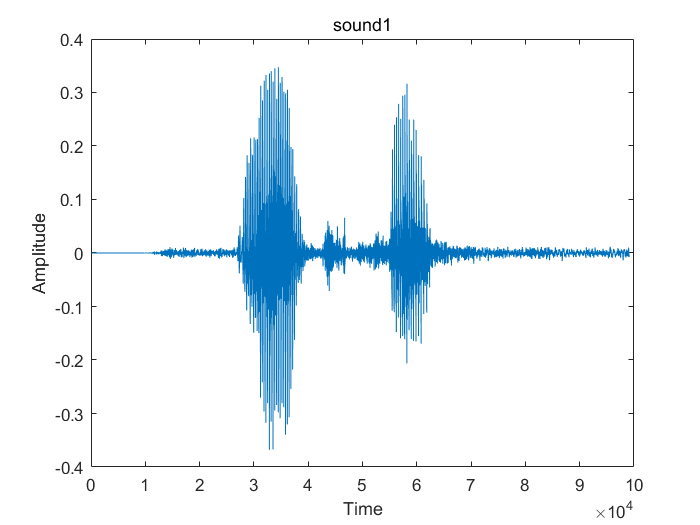

% % 任务1 信号还原
% [x0,fs0] = start_sound(start_filter, '', 0);
% 
% % 任务1 信号加噪
% Task_1_2

% 任务2 音频调制
% Task_2(1);

[sound1,fs1] = audioread("matlab.wav");
% 通道合并
sound1 = mean(sound1,2);
[sound2,fs2] = audioread("signal.wav");
sound2 = mean(sound2,2);

N1 = length(sound1);
n1 = 0:N1-1;

figure()
plot(n1,sound1) 
title('sound1');
xlabel('Time');
ylabel('Amplitude'); 

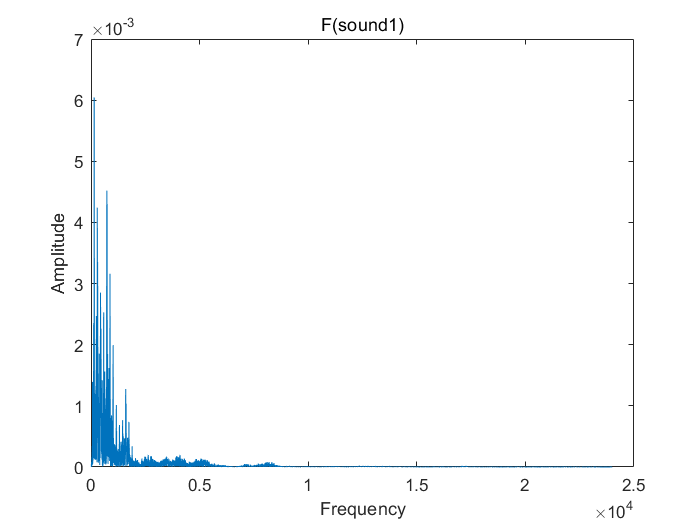

%     axis([0,2e5,-1,1]);

figure()
[F1,w1] = Fourier(fs1, sound1);
plot(w1,F1)
title("F(sound1)");
xlabel('Frequency');
ylabel('Amplitude'); 

function Task_2(show)
    [sound1,fs1] = audioread("matlab.wav");
    % 通道合并
    sound1 = mean(sound1,2);
    [sound2,fs2] = audioread("signal.wav");
    sound2 = mean(sound2,2);
    
    N1 = length(sound1);
    n1 = 0:N1-1;
    
    figure()
    plot(n1,sound1) 
    title('sound1');
    xlabel('Time');
    ylabel('Amplitude'); 
%     axis([0,2e5,-1,1]);
    
    figure()
    [F1,w1] = Fourier(fs1, sound1);
    plot(w1,F1)
    title("F(sound1)");
    xlabel('Frequency');
    ylabel('Amplitude'); 
%     xlim([0,6e3]);

    N2 = length(sound2);
    n2 = 0:N2-1;
    
    figure()
    plot(n2,sound2) 
    title('sound2');
    xlabel('Time');
    ylabel('Amplitude'); 
%     axis([0,2e5,-1,1]);
    
    figure()
    [F2,w2] = Fourier(fs2, sound2);
    plot(w2,F2)
    title("F(sound2)");
    xlabel('Frequency');
    ylabel('Amplitude');
%     xlim([0,6e3]);

    
    % 音频调制
    [am1, fc1] = AM(sound1,fs1, 3 ,show);
    [am2, fc2] = AM(sound2,fs2, 3 ,show);
       
    dam1 = deAM(am1, fs1, fc1, show);
    dam2 = deAM(am2, fs1, fc1, show);
%     audiowrite('dam1.wav',dam1,fs1)
%     audiowrite('dam2.wav',dam2,fs2)
    
    % 加噪声
    am1_1 = add_noise(am1, 30);
    am2_1 = add_noise(am2, 30);
    draw_f(am1_1, n1,fs1, 'noiseAdd1' )
    draw_f(am2_1, n2,fs2, 'noiseAdd2' )
    
    dam1_1 = deAM(am1_1, fs1, fc1, show);
    dam2_1 = deAM(am2_1, fs2, fc2, show);

    
    % 除噪声
%     am1_2 = filter(damfix1,am1_1);
%     am2_2 = filter(damfix2,am2_1);
%     draw_f(am1_2, n1,fs1, 'am1_2' )
%     draw_f(am2_2, n2,fs1, 'am2_2' )
    
%     dam1_2 = deAM(am1_2, fs1, fc1, show);
%     dam2_2 = deAM(am2_2, fs2, fc2, show);
    dam1_2 = filter(damfix1,dam1_1);
    dam2_2 = filter(damfix1,dam2_1);
    draw_f(dam1_2, n1, fs1, 'dam1_2')
    draw_f(dam2_2, n2, fs2, 'dam2_2')
    
%     audiowrite('dam2_2.wav',dam2_2,fs1)
%     audiowrite('dam1_2.wav',dam1_2,fs1)

%     audiowrite('dam1_2.wav',dam1_2,fs1)
%     audiowrite('dam2_2.wav',dam2_2,fs2)

%     N = length(dam1_2);
%     n3 = 0:N-1;
%     draw_f(dam1_2, n3,fs2, 'dam1_2' )
%   audiowrite('dam1_2.wav',dam1_2,fs1)
%     audiowrite('dam2_2.wav',dam2_2,fs2)
    
%     sound(sound2,fs2); pause;
%     sound(dam1_1,fs2); pause;
%     sound(dam2_2, fs2); pause;
end


function Task_1_2()
    [s,fs] = audioread("sound1.wav");
    N = length(s);
    n = 0:N-1;
    
    draw_f(s,n,fs,'s')
    
    
    % 高斯噪声
    s1_2 = add_noise(s, 10);
    draw_f(s1_2,n,fs,'s1_2')
    
    s1_1 = add_noise(s, 30);
    draw_f(s1_1,n,fs,'s1_1')
%     audiowrite('s1_1.wav',s1_1,fs)
    
   
    s1_3 = filter(s1f, s);
    draw_f(s1_3,n,fs,'s1_3')
%     audiowrite('s1_3.wav',s1_3,fs)

    % 单频噪声
    s2_1 = single_wave(s, 1e4, 1, fs);
    draw_f(s2_1,n,fs,'s2_1')
%     audiowrite('s2_1.wav',s2_1,fs)
    
    s2_2 = dewave(s2_1, 1e4, fs);
    draw_f(s2_2,n,fs,'s2_2')
%     audiowrite('s2_2.wav',s2_2,fs);

    % 多频噪声
    s3_1 = single_wave(s, 1e4, 1, fs);
    s3_1 = single_wave(s3_1, 1.5e4, 1, fs);
    s3_1 = single_wave(s3_1, 0.25e4, 1, fs);
    draw_f(s3_1,n,fs,'s3_1')
%     audiowrite('s3_1.wav',s3_1,fs)
    
    s3_2 = dewave(s3_1, 1e4, fs);
    s3_2 = dewave(s3_2, 0.25e4, fs);
    s3_2 = dewave(s3_2, 1.5e4, fs);
    draw_f(s3_2,n,fs,'s3_2')
%     audiowrite('s3_2.wav',s3_2,fs)
    
    % 其他噪声(chirp)
    s4_1 = chirp_noise(s, fs);
    draw_f(s4_1,n,fs,'s4_1')
%     audiowrite('s4_1.wav',s4_1,fs)
    
    s4_2 = filter(dechirp, s4_1);
    draw_f(s4_2,n,fs,'s4_2')
%     audiowrite('s4_2.wav',s4_2,fs)
    
end

function snew = dewave(s, fnoise, Fs)
    Fpass1 = fnoise - 500;            
    Fstop1 = fnoise - 250;            
    Fstop2 = fnoise + 250;           
    Fpass2 = fnoise + 500;          
    Dpass1 = 0.028774368332;  
    Dstop  = 0.001;           
    Dpass2 = 0.057501127785;  
    flag   = 'scale';         
    
    % Calculate the order from the parameters using KAISERORD.
    [N,Wn,BETA,TYPE] = kaiserord([Fpass1 Fstop1 Fstop2 Fpass2]/(Fs/2), [1 ...
                                 0 1], [Dpass1 Dstop Dpass2]);
    
    % Calculate the coefficients using the FIR1 function.
    b  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
    Hd = dfilt.dffir(b);
    
    snew = filter(Hd, s);
end

function s1 = chirp_noise(s, fs)
    dt=1/fs;    %时间采样间隔
    N=length(s);  %采样点数
    
    n = 0:N-1;
    t=n*dt; %采样时间
    
    noise=chirp(t, 1e4, 2, 1.5e4); 
    
    for i = n+1
        s1(i) = s(i) + noise(i);
    end
end

function s1 = single_wave(s, f, A, fs)
    dt=1/fs;%时间采样间隔
    fmax=f;  %信源最高频率
    
    N=length(s);  %采样点数
    
    n = 0:N -1;
    t=n*dt; %采样时间
    
    noise=A*cos(2*pi*fmax*t);
%     draw_f(noise,[0:N-1],fs,'noise')
    
    for i = n+1
        s1(i) = s(i) + noise(i);
    end
    
end

function y = add_noise(x, snr)
    % 信噪比和信号指定功率
    px_dBW=0;
    % 调用randn函数产生噪声序列再叠加
    pn_W=10^((px_dBW-snr)/10);
    n=sqrt(pn_W)*randn(1,length(x));
    y=x+n';
end

function [Dam] = deAM(Uam, fs, fc, show)
    N=length(Uam);  %采样点数
    n = (0:N-1);

    Dam=demod(Uam,fc,fs,'am');  % 对信号进行解调
    
    if show == 1
        draw_f(Dam, n, fs, 'dam')
    end
end

function [Uam, fc] = AM(mt, fs, A1, show)
    fc=fs/10;            %载波信号频率
    

    N=length(mt);  %采样点数
    n = (0:N-1);
     
    mes=1+A1*mt;          %调制信号
    Uam=modulate(mes,fc,fs,'am'); 	 %AM已调信号
    
    if show==1
        draw_f(Uam, n, fs, 'am')
    end
    
    
end

function [x0, fs0] = start_sound(ftr, name, play)
    [x1,fs1]=audioread('noised.wav'); %打开语音信号

    N = length(x1);
%     sound(x1,fs1);
    %做原始语音信号的时域波形图
    n=0:N-1;
    
    figure()
    plot(n,x1) 
    title('x1');
    xlabel('Time');
    ylabel('Amplitude'); 
    axis([0,2e5,-1,1]);
    
    figure()
    [F1,w1] = Fourier(fs1, x1);
    plot(w1,F1)
    title("F(x1)");
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,6e3]);
    
    %低通滤波
    soundX0 = filter(ftr,x1);
    soundX0 = soundX0 .* 20;
    
    %复原信号的图像
    figure()
    plot(n,soundX0) 
    title('soundX0');
    xlabel('Time');
    ylabel('Amplitude'); 
    axis([0,2e5,-1,1]);
    
    figure()
    [F0,w0] = Fourier(fs1, soundX0);
    plot(w0,F0)
    title("F(soundX0)");
    xlabel('Frequency');
    ylabel('Amplitude'); 
    xlim([0,6e3]);
    
    
    if play == 1
        sound(soundX0,fs1);
    end
    
    if ~isempty(name)
        audiowrite(name,soundX0,fs1)
    end
    
    fs0 = fs1;
    x0 = soundX0;
end

function [F, w] = Fourier(Fs, fin)
    y = fft(fin); 

    n = length(fin);                         

    F=2*abs(y(1:n/2+1))/n;
    w=(0:n/2)*(Fs/n);
end

% function [fin, n] = inFourier(F)
%     N = length(F);
%     yHalf = N.*F./2;
%     y = [fliplr(yHalf) yHalf];
%     fin = ifft(y);
%     n = 0:N-1;
% end

% function[f,sf]=FFT_SHIFT(t,st)
%     dt=t(2)-t(1);
%     T=t(end);
%     df=1/T;
%     N=length(st);
%     f=[-N/2:N/2-1]*df;
%     sf=fft(st);
%     sf=T/N*fftshift(sf);
% end
% 
% 
% 
% function[t,st]=F2T(f,Sf)
%     df=f(2)-f(1);
%     fmax=(f(end)-f(1)+df);
%     dt=1/fmax;
%     N=length(f);
%     t=[0:N-1] * dt;
%     Sf=fftshift(Sf);
%     st=fmax * ifft(Sf);
%     st=real(st);
% end

function draw_f(x1,n,fs1,name)
    figure()
    plot(n,x1) 
    title(name);
    xlabel('Time');
    ylabel('Amplitude'); 
    
    figure()
    [F1,w1] = Fourier(fs1, x1);
    plot(w1,F1)
    title(name);
    xlabel('Frequency');
    ylabel('Amplitude'); 
    ylim([0, 7e-3])
end